# Lecture 19

## Exercise 7

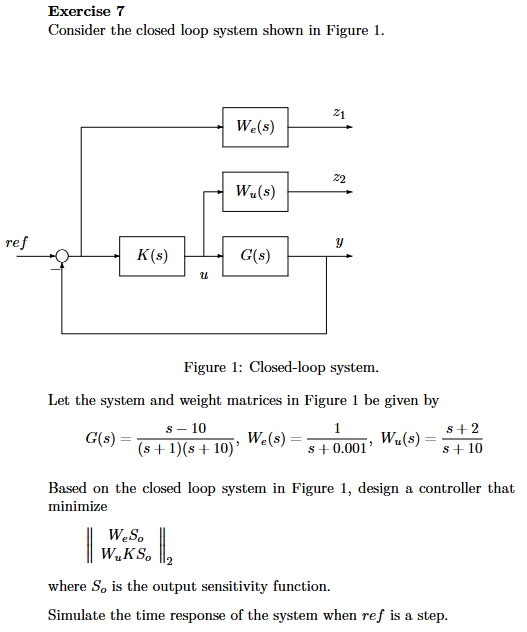

% Get state space models from transfer functions
w = logspace(-2, 4, 100);
[A,B,C,D] = tf2ss([1 -10], [1 11 10]);
[Ae,Be,Ce,De] = tf2ss([1], [1 0.001]);
[Au,Bu,Cu,Du] = tf2ss([1 2], [1 10]);

G = ss(A,B,C,D);
We = ss(Ae,Be,Ce,De);
Wu = ss(Au,Bu,Cu,Du);

% Set up P
G.InputName = "u"; G.OutputName = "y";
Wu.InputName = "u"; Wu.OutputName = "z2";
We.InputName = "e"; We.OutputName = "z1";
S1 = sumblk("e = ref - y");

P = connect(G, We, Wu, S1, {"ref", "u"}, {"z1", "z2", "e"});

% H2 controller design
[K, CL, gamma] = h2syn(P, 1, 1);
display(gamma) % gamma being the H2 norm

gamma = 1.0627

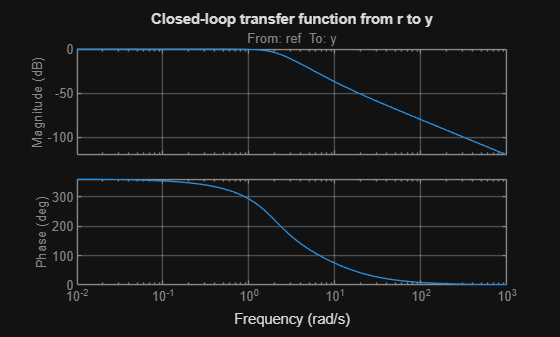


% Calculation of closed-loop without weight functions
% Assume G and k2 are already defined as ss models

% Assign input/output names
G.InputName = "u";    % input to G is u
G.OutputName = "y";   % output of G is y

K.InputName = "e";   % input to k2 is error signal e
K.OutputName = "u";  % output of k2 is control u

% Define the error signal: e = dist1 - y
S2 = sumblk("e = ref - y");

% Connect the system
P_cl = connect(G, K, S2, "ref", "y");  % input: dist1, output: y

figure(1)
bode(P_cl)
grid on
title('Closed-loop transfer function from r to y')

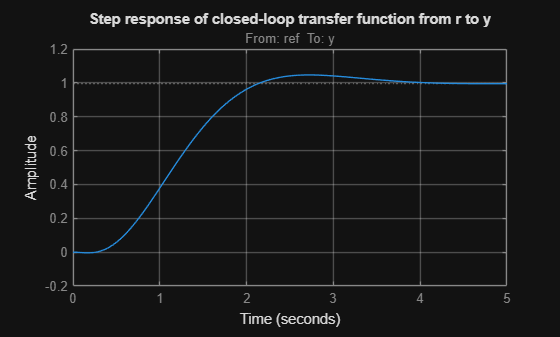

figure(2)
step(P_cl)
grid on
title('Step response of closed-loop transfer function from r to y')

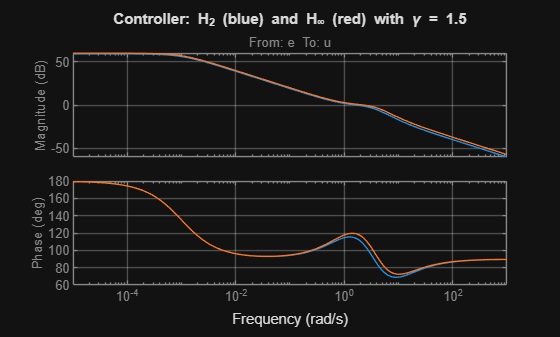

% Controller design using mixsyn from H_infinity design
% Use gamma = 1.5 and 10
G = ss(A,B,C,D);
We = ss(Ae,Be,Ce,De);
Wu = ss(Au,Bu,Cu,Du);
Wy = [];
g0 = 1.5;
[K2,CL1,gamma1] = mixsyn(G, We, Wu, Wy, g0);
g1 = 10;
[K3,CL2,gamma2] = mixsyn(G, We, Wu, Wy, g1);

figure(3)
bode(K, K2)
grid on
title('Controller: H_2 (blue) and H_{\infty} (red) with \gamma = 1.5')

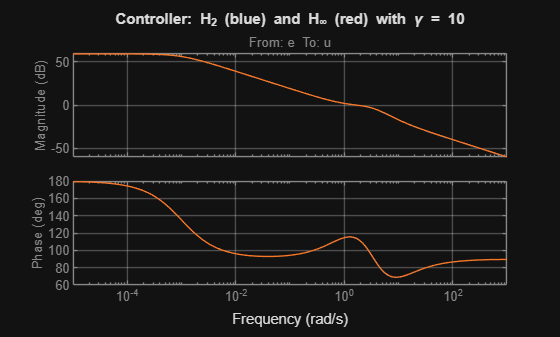

figure(4)
bode(K, K3)
grid on
title('Controller: H_2 (blue) and H_{\infty} (red) with \gamma = 10')

## Exercise 8